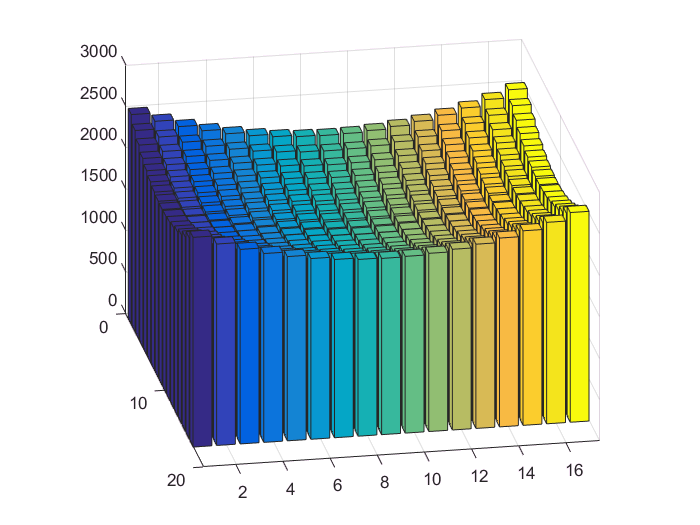

N = 64;
formation = zeros(N,2);
formation(1:(N/4),1) = (0:(N/4-1))'*3;
formation((N/4+1):(2*N/4),2) = (0:(N/4-1))'*3;
formation((N/4+1):(2*N/4),1) = ones(N/4,1)*3*N/4;
formation((2*N/4+1):(3*N/4),2) = ones(N/4,1)*3*N/4;
formation((2*N/4+1):(3*N/4),1) = (ones(N/4,1)*(N/4+1)-(1:(N/4))')*3;
formation((3*N/4+1):N,2) = (ones(N/4,1)*(N/4+1)-(1:(N/4))')*3;

distance=zeros(N/4+1);
for i=1:(N/4+1)
    for j=1:(N/4+1)
        for k=1:N
           distance(i,j) = distance(i,j)+sqrt((formation(k,1)-3*(i-1))^2+(formation(k,2)-3*(j-1))^2); 
        end
    end
end
  bar3(distance)